# Slosh 3D, tilt about y axis 

Different parametrization of the pendulum

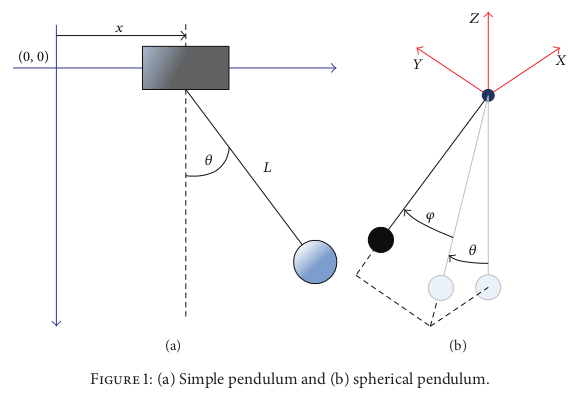

In this code the equation of motion for the pendulum angle representing the sloshing are derived through the use of the Euler-Lagrange equations.

This sloshing model represent only the 3D motion of the tray and a 1D rotation about the y axis of the container.

clc 
clear all

syms theta(t) psi(t) phi(t) beta(t)
syms t 
syms dx dy dz h l m g M b cs
syms x0(t) y0(t) z0(t)
sympref('AbbreviateOutput',false);

$\theta$ = angle between plane ZY and the mass, angle of the pendulum mapped in xz plane

$\phi$ = angle in the perpendicular direction, between the original pendulum and the mapped pendulum

$\psi$ =  rotation of the pendulum about its longitudinal axis z

$\beta$ = pitch rotation about the y axis of the container

h = height of the container

d = distance from CoM to top of the liquid at rest (for full uniform liquid container it is h/2)

l = length of pendulum

m = mass of pendulum

M = mass of liquid + container

b = damping coefficient

J = moment of inertia of the pendulum mass

## Derivation of the pendulum coordinates

Through the use of homogeneous transformation matrices infer the position of the pendulum mass and of the liquid+container mass in the world reference frame.

Assume the following reference frames:

- Inertial frame

- Frame of the container CoM with origin assumed to be at a distance d from the pivot

- Frame of the pivot of the pendulum

- Frame of the pendulum mass

### World to Cylinder base

Derive the homogeneous transformation matrix from the world to the CoM reference frame.

Define rotation matrix (rotation of around the y-axis)

% Rotation matrix about y-axis of angle beta
R = eye(3);

Define translation vector

p = [x0; y0; z0];

Create homogeneous transformation matrix

T_w0 = [R, p; 0 0 0 1];
T_w0 = formula(T_w0);

% Display the transformation matrix
disp('Homogeneous Transformation Matrix from world to cylinder base:');

Homogeneous Transformation Matrix from world to cylinder base:


disp(T_w0);

$$\left(\begin{array}{cccc} 1 & 0 & 0 & x_{0}\left(t\right)\\ 0 & 1 & 0 & y_{0}\left(t\right)\\ 0 & 0 & 1 & z_{0}\left(t\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

### Cylinder base to CoR

Derive the homogeneous transformation matrix from the world to the CoM reference frame.

Define rotation matrix (rotation of around the y-axis)

% Rotation matrix about y-axis of angle beta
R_y_beta = [cos(beta),  0, sin(beta); 
             0,           1,           0; 
             -sin(beta),  0,  cos(beta)];
R_y_beta=formula(R_y_beta)

$$R\_y\_beta = \left(\begin{array}{ccc} \cos\left(\beta \left(t\right)\right) & 0 & \sin\left(\beta \left(t\right)\right)\\ 0 & 1 & 0\\ -\sin\left(\beta \left(t\right)\right) & 0 & \cos\left(\beta \left(t\right)\right) \end{array}\right)$$

Define translation vector (h = h - Ln)

p = [0; 0; h + dz];

Create homogeneous transformation matrix

T_0t = [R_y_beta, p; 0 0 0 1];
T_0t = formula(T_0t);

% Display the transformation matrix
disp('Homogeneous Transformation Matrix from cylinder base to CoR:');

Homogeneous Transformation Matrix from cylinder base to CoR:


disp(T_0t);

$$\left(\begin{array}{cccc} \cos\left(\beta \left(t\right)\right) & 0 & \sin\left(\beta \left(t\right)\right) & 0\\ 0 & 1 & 0 & 0\\ -\sin\left(\beta \left(t\right)\right) & 0 & \cos\left(\beta \left(t\right)\right) & \mathrm{dz}+h\\ 0 & 0 & 0 & 1 \end{array}\right)$$

### CoR to pivot

Derive the homogeneous transformation matrix from the CoM reference frame to the pivot reference frame.

Define rotation matrices

% Rotation matrix about y-axis of angle -theta
R_y_theta = [cos(-theta),  0, sin(-theta); 
             0,           1,           0; 
             -sin(-theta),  0,  cos(-theta)];
R_y_theta = formula(R_y_theta)

$$R\_y\_theta = \left(\begin{array}{ccc} \cos\left(\theta \left(t\right)\right) & 0 & -\sin\left(\theta \left(t\right)\right)\\ 0 & 1 & 0\\ \sin\left(\theta \left(t\right)\right) & 0 & \cos\left(\theta \left(t\right)\right) \end{array}\right)$$


% Rotation matrix about x-axis of angle phi
R_x_phi = [1,          0,          0; 
           0,   cos(phi),  -sin(phi); 
           0,   sin(phi),  cos(phi)];
R_x_phi=formula(R_x_phi)

$$R\_x\_phi = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & \cos\left(\varphi \left(t\right)\right) & -\sin\left(\varphi \left(t\right)\right)\\ 0 & \sin\left(\varphi \left(t\right)\right) & \cos\left(\varphi \left(t\right)\right) \end{array}\right)$$


R_combined = R_y_theta * R_x_phi 

$$R\_combined = \left(\begin{array}{ccc} \cos\left(\theta \left(t\right)\right) & -\sin\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right) & -\cos\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\\ 0 & \cos\left(\varphi \left(t\right)\right) & -\sin\left(\varphi \left(t\right)\right)\\ \sin\left(\theta \left(t\right)\right) & \cos\left(\theta \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right) & \cos\left(\varphi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right) \end{array}\right)$$

Define translation vector (from the CoM reference frame)

p = [0; 0; -dz];

Create homogeneous transformation matrix

T_tp = [R_combined, p; 0 0 0 1];
T_tp = formula(T_tp);

% Display the transformation matrix
disp('Homogeneous Transformation Matrix from CoR to pivot:');

Homogeneous Transformation Matrix from CoR to pivot:


disp(T_tp);

$$\left(\begin{array}{cccc} \cos\left(\theta \left(t\right)\right) & -\sin\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right) & -\cos\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right) & 0\\ 0 & \cos\left(\varphi \left(t\right)\right) & -\sin\left(\varphi \left(t\right)\right) & 0\\ \sin\left(\theta \left(t\right)\right) & \cos\left(\theta \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right) & \cos\left(\varphi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right) & -\mathrm{dz}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

### Pivot to Pendulum mass

R = eye(3)

R =      1     0     0
     0     1     0
     0     0     1


Define translation vector

p = [0; 0; -l];

Define the position of the pendulum mass in the static reference frame fixed to the pivot

T_pm = [R, p; 0 0 0 1];
T_pm = formula(T_pm);

% Display the transformation matrix
disp('Homogeneous Transformation Matrix from pivot to mass:');

Homogeneous Transformation Matrix from pivot to mass:


disp(T_pm);

$$\left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & -l\\ 0 & 0 & 0 & 1 \end{array}\right)$$

### Pendulum mass coordinates in inertial frame

Derive the homogeneous transformation from inertial frame to pendulum mass.

T_wm = T_w0*T_0t*T_tp*T_pm

Derive the coordinates of the pendulum mass

xm = T_wm(1,4)

$$xm = x_{0}\left(t\right)-\mathrm{dz}\,\sin\left(\beta \left(t\right)\right)+l\,\left(\cos\left(\beta \left(t\right)\right)\,\cos\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)-\cos\left(\varphi \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\right)$$

ym = T_wm(2,4)

$$ym = y_{0}\left(t\right)+l\,\sin\left(\varphi \left(t\right)\right)$$

zm = T_wm(3,4)

$$zm = \mathrm{dz}+h+z_{0}\left(t\right)-l\,\left(\cos\left(\beta \left(t\right)\right)\,\cos\left(\varphi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)+\cos\left(\varphi \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\right)-\mathrm{dz}\,\cos\left(\beta \left(t\right)\right)$$

Explicitate the relative position of the pendulum mass with respect to its pivot

xr = l*cos(phi)*sin(theta);
yr = l*sin(phi);
zr = -l*cos(phi)*cos(theta);

## Derivation of the equations of motion

Derive the equation of motion finding kinetic and potential energies and then assembling the lagrangian equation with respect to theta.

### Kinetic Energy

xm_dot = diff(xm, t);
ym_dot = diff(ym, t);
zm_dot = diff(zm, t);

xr_dot = diff(xr, t);
yr_dot = diff(yr, t);
zr_dot = diff(zr, t);

#### Kinetic energy for the pendulum

Sum the contributions of the kinetic energies in x, y and z

Tmx = 0.5 * m * xm_dot^2;
Tmx = simplify(Tmx)

$$Tmx = \frac{m\,{\left(\frac{\partial }{\partial t}x_{0}\left(t\right)-\mathrm{dz}\,\cos\left(\beta \left(t\right)\right)\,\frac{\partial }{\partial t}\beta \left(t\right)-l\,\cos\left(\beta \left(t\right)\right)\,\cos\left(\varphi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\beta \left(t\right)+l\,\cos\left(\beta \left(t\right)\right)\,\cos\left(\varphi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)-l\,\cos\left(\varphi \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\beta \left(t\right)-l\,\cos\left(\beta \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)+l\,\sin\left(\beta \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)+l\,\cos\left(\varphi \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}}{2}$$

%disp(latex(Tmx))

Tmy = 0.5 * m * ym_dot^2;
Tmy = simplify(Tmy)

$$Tmy = \frac{m\,{\left(\frac{\partial }{\partial t}y_{0}\left(t\right)+l\,\cos\left(\varphi \left(t\right)\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)\right)}^{2}}{2}$$

%disp(latex(Tmx))

Tmz = 0.5 * m * zm_dot^2;
Tmz = simplify(Tmz)

$$Tmz = \frac{m\,{\left(\frac{\partial }{\partial t}z_{0}\left(t\right)+\mathrm{dz}\,\sin\left(\beta \left(t\right)\right)\,\frac{\partial }{\partial t}\beta \left(t\right)-l\,\cos\left(\beta \left(t\right)\right)\,\cos\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\beta \left(t\right)+l\,\cos\left(\varphi \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\beta \left(t\right)+l\,\cos\left(\beta \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)+l\,\cos\left(\beta \left(t\right)\right)\,\cos\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)-l\,\cos\left(\varphi \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)+l\,\sin\left(\beta \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)\right)}^{2}}{2}$$

%disp(latex(Tmz))

Tm = Tmx + Tmy + Tmz

T = Tm;


### Potential energy

%% Potential energy
Um = m * g * zm;

U = Um;
U = simplify(U);
disp("Potential energy:");

Potential energy:


disp(U);

$$g\,m\,\left(\mathrm{dz}+h+z_{0}\left(t\right)-\mathrm{dz}\,\cos\left(\beta \left(t\right)\right)-l\,\cos\left(\beta \left(t\right)\right)\,\cos\left(\varphi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)-l\,\cos\left(\varphi \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\right)$$

### Rayleigh function

To account for dissipied energy

theta_dot = diff(theta, t);
phi_dot = diff(phi, t);

Derive velocity of the relative pendulum mass

v2 = xr_dot^2 + yr_dot^2+ zr_dot^2;

D = b/2 *(v2);

D_dthetadot = diff(D, theta_dot);
D_dphidot = diff(D, phi_dot);

### Lagrangian

%% Lagrangian 
L = T - U;
L = simplify(L)


% wrt theta
L_thetadot = diff(L, diff(theta(t), t));
L_thetadot = simplify(L_thetadot);

dL_theta_dot = diff(L_thetadot, t);
dL_theta_dot = simplify(dL_theta_dot);

L_theta = diff(L, theta(t));
L_theta = simplify(L_theta)


% wrt phi
L_phi_dot = diff(L, diff(phi(t), t));
L_phi_dot = simplify(L_phi_dot);

dL_phi_dot = diff(L_phi_dot, t);
dL_phi_dot = simplify(dL_phi_dot);

L_phi = diff(L, phi(t));
L_phi = simplify(L_phi);

### Equations of motion

%for theta, that represents the swing of the pendulum and, accordingly, the sloshing dynamics.
eqn_theta = dL_theta_dot - L_theta + D_dthetadot;
% eqn_theta = eqn_theta + b * diff(theta, t);
eqn_theta = simplify(eqn_theta);
disp("Equation of motion with respect to theta:");

Equation of motion with respect to theta:


disp(eqn_theta);

$$-l\,\cos\left(\varphi \left(t\right)\right)\,\left(g\,m\,\sin\left(\beta \left(t\right)-\theta \left(t\right)\right)-m\,\cos\left(\beta \left(t\right)-\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}x_{0}\left(t\right)+m\,\sin\left(\beta \left(t\right)-\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}z_{0}\left(t\right)-b\,l\,\cos\left(\varphi \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)-\mathrm{dz}\,m\,\sin\left(\theta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\beta \left(t\right)\right)}^{2}+\mathrm{dz}\,m\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\beta \left(t\right)+l\,m\,\cos\left(\varphi \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\beta \left(t\right)-l\,m\,\cos\left(\varphi \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)+2\,l\,m\,\sin\left(\varphi \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)-2\,l\,m\,\sin\left(\varphi \left(t\right)\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)\,\frac{\partial }{\partial t}\beta \left(t\right)\right)$$

disp("Latex Equation of motion with respect to theta:");

Latex Equation of motion with respect to theta:


disp(latex(eqn_theta));

-l\,\cos\left(\phi \left(t\right)\right)\,\left(g\,m\,\sin\left(\beta \left(t\right)-\theta \left(t\right)\right)-m\,\cos\left(\beta \left(t\right)-\theta \left(t\right)\right)\,\frac{\partial ^2}{\partial t^2} x_{0}\left(t\right)+m\,\sin\left(\beta \left(t\right)-\theta \left(t\right)\right)\,\frac{\partial ^2}{\partial t^2} z_{0}\left(t\right)-b\,l\,\cos\left(\phi \left(t\right)\right)\,\frac{\partial }{\partial t} \theta \left(t\right)-\mathrm{dz}\,m\,\sin\left(\theta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t} \beta \left(t\right)\right)}^2+\mathrm{dz}\,m\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial ^2}{\partial t^2} \beta \left(t\right)+l\,m\,\cos\left(\phi \left(t\right)\right)\,\frac{\partial ^2}{\partial t^2} \beta \left(t\right)-l\,m\,\cos\left(\phi \left(t\right)\right)\,\frac{\partial ^2}{\partial t^2} \theta \left(t\right)+2\,l\,m\,\sin\left(\phi \left(t\right)\right)\,\frac{\partial }{\partial t} \theta \left(t\right)\,\frac{\partial }{\partial t}


syms c_theta s_theta c_phi s_phi c_beta s_beta
syms theta_dot phi_dot theta_ddot phi_ddot beta_dot beta_ddot x_ddot y_ddot z_ddot 
eq_sub1 = subs(eqn_theta,[cos(theta(t)), sin(theta(t)), cos(phi(t)), sin(phi(t)), cos(beta(t)),sin(beta(t))],[c_theta s_theta c_phi s_phi c_beta s_beta]);
eq_sub2 = subs(eq_sub1, [diff(diff(theta(t),t),t),diff(diff(phi(t),t),t),diff(diff(beta(t),t),t),diff(diff(x0(t),t),t),diff(diff(y0(t),t),t),diff(diff(z0(t),t),t)],[theta_ddot,phi_ddot,beta_ddot,x_ddot,y_ddot,z_ddot ]);
eq_sub3 = subs(eq_sub2, [diff(theta(t),t),diff(phi(t),t),diff(beta(t),t)],[theta_dot,phi_dot,beta_dot]);


% eqn1 = isolate(eq_sub2 == 0, diff(theta(t),t,t));
eqn1 = isolate(eq_sub3 == 0, theta_ddot);

disp(eqn1);

$$\ddot{\theta }=\frac{-\mathrm{dz}\,m\,s_{\theta }\,{\dot{\beta }}^{2}-2\,l\,m\,\dot{\varphi }\,s_{\varphi }\,\dot{\beta }+g\,m\,\sin\left(\beta \left(t\right)-\theta \left(t\right)\right)-m\,\ddot{x}\,\cos\left(\beta \left(t\right)-\theta \left(t\right)\right)+m\,\ddot{z}\,\sin\left(\beta \left(t\right)-\theta \left(t\right)\right)-b\,c_{\varphi }\,l\,\dot{\theta }+\ddot{\beta }\,c_{\theta }\,\mathrm{dz}\,m+\ddot{\beta }\,c_{\varphi }\,l\,m+2\,l\,m\,\dot{\varphi }\,s_{\varphi }\,\dot{\theta }}{c_{\varphi }\,l\,m}$$

%for phi
eqn_phi = dL_phi_dot - L_phi + D_dphidot;
% eqn_phi = eqn_phi + b * diff(phi, t);
eqn_phi = simplify(eqn_phi);
disp("Equation of motion with respect to phi:");

Equation of motion with respect to phi:


disp(eqn_phi);

$$b\,l^{2}\,\frac{\partial }{\partial t}\varphi \left(t\right)+l^{2}\,m\,\frac{\partial^{2}}{\partial t^{2}}\varphi \left(t\right)+\frac{l^{2}\,m\,\sin\left(2\,\varphi \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\beta \left(t\right)\right)}^{2}}{2}+\frac{l^{2}\,m\,\sin\left(2\,\varphi \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}}{2}+l\,m\,\cos\left(\varphi \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}y_{0}\left(t\right)-l^{2}\,m\,\sin\left(2\,\varphi \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\,\frac{\partial }{\partial t}\beta \left(t\right)+\mathrm{dz}\,l\,m\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\beta \left(t\right)\right)}^{2}+l\,m\,\cos\left(\beta \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}z_{0}\left(t\right)-l\,m\,\cos\left(\beta \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}x_{0}\left(t\right)+l\,m\,\sin\left(\beta \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}x_{0}\left(t\right)+l\,m\,\sin\left(\beta \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}z_{0}\left(t\right)+\mathrm{dz}\,l\,m\,\sin\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\beta \left(t\right)+g\,l\,m\,\cos\left(\beta \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)+g\,l\,m\,\sin\left(\beta \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)$$

disp("Latex Equation of motion with respect to phi:");

Latex Equation of motion with respect to phi:


disp(latex(eqn_phi));

b\,l^2\,\frac{\partial }{\partial t} \phi \left(t\right)+l^2\,m\,\frac{\partial ^2}{\partial t^2} \phi \left(t\right)+\frac{l^2\,m\,\sin\left(2\,\phi \left(t\right)\right)\,{\left(\frac{\partial }{\partial t} \beta \left(t\right)\right)}^2}{2}+\frac{l^2\,m\,\sin\left(2\,\phi \left(t\right)\right)\,{\left(\frac{\partial }{\partial t} \theta \left(t\right)\right)}^2}{2}+l\,m\,\cos\left(\phi \left(t\right)\right)\,\frac{\partial ^2}{\partial t^2} y_{0}\left(t\right)-l^2\,m\,\sin\left(2\,\phi \left(t\right)\right)\,\frac{\partial }{\partial t} \theta \left(t\right)\,\frac{\partial }{\partial t} \beta \left(t\right)+\mathrm{dz}\,l\,m\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\phi \left(t\right)\right)\,{\left(\frac{\partial }{\partial t} \beta \left(t\right)\right)}^2+l\,m\,\cos\left(\beta \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\phi \left(t\right)\right)\,\frac{\partial ^2}{\partial t^2} z_{0}\left(t\right)-l\,m\,\cos\left(\beta \left(t\right)\righ


syms c_theta s_theta c_phi s_phi c_beta s_beta c_gamma s_gamma
syms theta_dot phi_dot theta_ddot phi_ddot beta_dot beta_ddot x_ddot y_ddot z_ddot 
eq_sub1 = subs(eqn_phi,[cos(theta(t)), sin(theta(t)), cos(phi(t)), sin(phi(t)), cos(beta(t)),sin(beta(t))],[c_theta s_theta c_phi s_phi c_beta s_beta]);
eq_sub2 = subs(eq_sub1, [diff(diff(theta(t),t),t),diff(diff(phi(t),t),t),diff(diff(beta(t),t),t),diff(diff(x0(t),t),t),diff(diff(y0(t),t),t),diff(diff(z0(t),t),t)],[theta_ddot,phi_ddot,beta_ddot,x_ddot,y_ddot,z_ddot ]);
eq_sub3 = subs(eq_sub2, [diff(theta(t),t),diff(phi(t),t),diff(beta(t),t)],[theta_dot,phi_dot,beta_dot]);


% eqn2 = isolate(eqn_phi == 0, diff(phi(t),t,t));
eqn2 = isolate(eq_sub3 == 0, phi_ddot);
disp(eqn2);

$$\ddot{\varphi }=-\frac{b\,l^{2}\,\dot{\varphi }+\frac{{\dot{\beta }}^{2}\,l^{2}\,m\,\sin\left(2\,\varphi \left(t\right)\right)}{2}+c_{\varphi }\,l\,m\,\ddot{y}+\frac{l^{2}\,m\,{\dot{\theta }}^{2}\,\sin\left(2\,\varphi \left(t\right)\right)}{2}-\dot{\beta }\,l^{2}\,m\,\dot{\theta }\,\sin\left(2\,\varphi \left(t\right)\right)+l\,m\,s_{\beta }\,s_{\varphi }\,s_{\theta }\,\ddot{z}+{\dot{\beta }}^{2}\,c_{\theta }\,\mathrm{dz}\,l\,m\,s_{\varphi }+c_{\beta }\,c_{\theta }\,g\,l\,m\,s_{\varphi }+\ddot{\beta }\,\mathrm{dz}\,l\,m\,s_{\varphi }\,s_{\theta }+c_{\beta }\,c_{\theta }\,l\,m\,s_{\varphi }\,\ddot{z}+g\,l\,m\,s_{\beta }\,s_{\varphi }\,s_{\theta }-c_{\beta }\,l\,m\,s_{\varphi }\,s_{\theta }\,\ddot{x}+c_{\theta }\,l\,m\,s_{\beta }\,s_{\varphi }\,\ddot{x}}{l^{2}\,m}$$


% syms c_theta s_theta c_phi s_phi c_beta s_beta  
% syms theta_dot phi_dot theta_ddot phi_ddot beta_dot beta_ddot  x_ddot y_ddot z_ddot 
% 
% eq_sub11 = subs(eqn2,[cos(theta(t)), sin(theta(t)), cos(phi(t)), sin(phi(t)), cos(beta(t)),sin(beta(t)), cos(gamma(t)),sin(gamma(t))],[c_theta s_theta c_phi s_phi c_beta s_beta c_gamma s_gamma]);
% % eq_sub11 = subs(eq_sub11,[c_phi^2+s_phi^2,c_theta^2+s_theta^2,c_beta^2+s_beta^2,c_gamma^2+s_gamma^2],[1 1 1 1]);
% eq_sub21 = subs(eq_sub11, [diff(diff(theta(t),t),t),diff(diff(phi(t),t),t),diff(diff(beta(t),t),t),diff(diff(gamma(t),t),t),diff(diff(x0(t),t),t),diff(diff(y0(t),t),t),diff(diff(z0(t),t),t)],[theta_ddot,phi_ddot,beta_ddot,gamma_ddot,x_ddot,y_ddot,z_ddot ]);
% 
% eq_sub31 = subs(eq_sub21, [diff(theta(t),t),diff(phi(t),t),diff(beta(t),t),diff(gamma(t),t)],[theta_dot,phi_dot,beta_dot,gamma_dot]);
% 

